clear; close all;

# Tutorial: Crater Ellipse Fitting

This software is made available under the MIT license. See SONIC/LICENSE for details.

In this example, we will be using `SONIC` to perform crater ellipse fitting using an image of Ceres, as captured by the Dawn spacecraft. We will first pull in the crater image and the extracted points around the crater rim. Then, we will use the `EllipseFitter` class in `SONIC` to fit an ellipse to the crater points. In an OPNAV routine, after performing crater identification, we can leverage estimated crater ellipse fits in the captured image and performing matching with a crater database (e.g., Robbins crater database) to extract pose information and perform triangulation.  

### Load Image and Extracted Crater Rim Points

First, we read in the image we are going to be analyzing as well as the series of points along the extracted crater rims, defined as 2D points in pixel space. 

imgPath = '+examples/+data/FC21B0043185_15267083218F1E.png';
load('+examples/+data/craterRimPoints.mat');

### Show Image of Raw Crater Rim Points

We next display the captured image of the surface of Ceres, overlayed with the raw points of two extracted crater rims in the image.

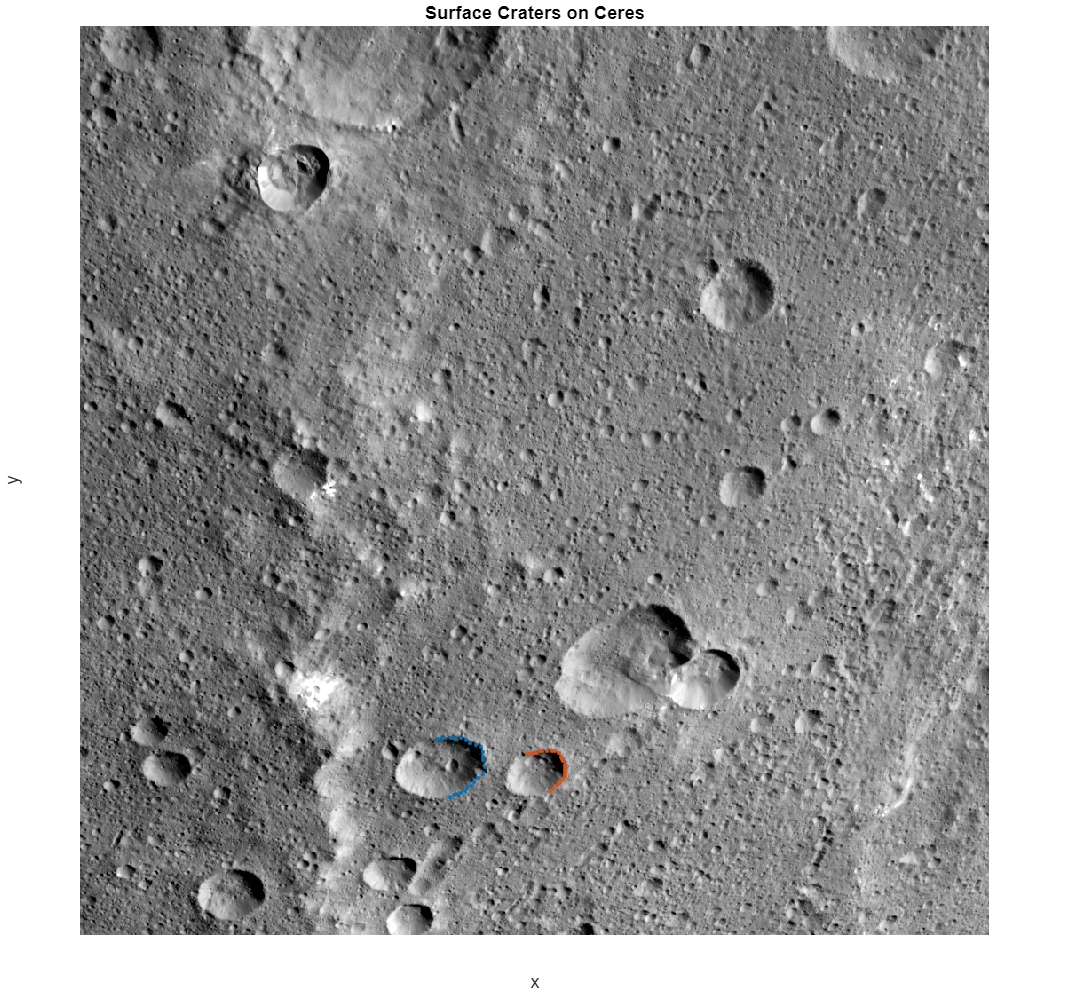

figure(1);
imshow(imgPath); hold on; title('Surface Craters on Ceres');
xlabel('x'); ylabel('y');
ncraters = length(xcraterPtsAll);
for i=1:ncraters
    xcraterPts = xcraterPtsAll{i}; ycraterPts = ycraterPtsAll{i};
    plot(xcraterPts, ycraterPts, '.');
end
hold off;

### Perform Various Ellipse Fitting Methods

For each crater, we create and save `SONIC` `Points2` objects for the extracted points along each crater rim.

craterPts = cell(1,ncraters);
for i = 1:ncraters
    xcraterPts = xcraterPtsAll{i}; ycraterPts = ycraterPtsAll{i};
    XYorig = sonic.Points2([xcraterPts' ; ycraterPts']);
    craterPts{i} = XYorig;
end

### Perform Various Ellipse Fitting Methods

Now, we will obtain crater ellipse fits using various fitting techniques. In particular, we will use traditional least squares as well as two unbiased ellipse fitting methods: semi-hyper least squares and hyper least squares [1].

First, we define the fitting methods we are interested in using. `'ls'` denotes least squares, `'shls'` denotes semi-hyper least squares, and `'hls'` denotes hyper least squares. Then, for each crater, we provide the corresponding `Points2` object of the crater points to the `fitEllipse` function to get our fit. The output of this is a `Conic` object, from which you can extract the conic fit in multiple formats, including a 6D vector for the implicit representation of the conic as well as a 5D vector of the explicit representation. 

We can also extract the analytical covariance matrix for each conic fit, using the function `getEllipseCovariance`. The output covariance will be an error covariance of the implicit parameters of the conic and will depend on the estimated pixel-level error of the crater rim points. In this case we use a pixel-level standard deviation of 5 pixels to estimate our conic fit covariance.

fitMthds = {'ls', 'shls', 'hls'}; 
nfitMthds = length(fitMthds);
conicFits = cell(ncraters,nfitMthds);
conicCovs = cell(ncraters,nfitMthds);
sigXY_px = 5;
for i = 1:ncraters
    XYorig = craterPts{i};
    for j = 1:nfitMthds
        conicObj = sonic.EllipseFitter.fitEllipse(XYorig,fitMthds{j});
        conicFits{i,j} = conicObj;
        conicCovs{i,j} = sonic.EllipseFitter.getEllipseCovariance(conicObj, XYorig, sigXY_px);
    end
end

### Plot Close-Up of Fitting Methods

Let's now plot and take a closer look at the different ellipse fitting methods, to see how they compare.

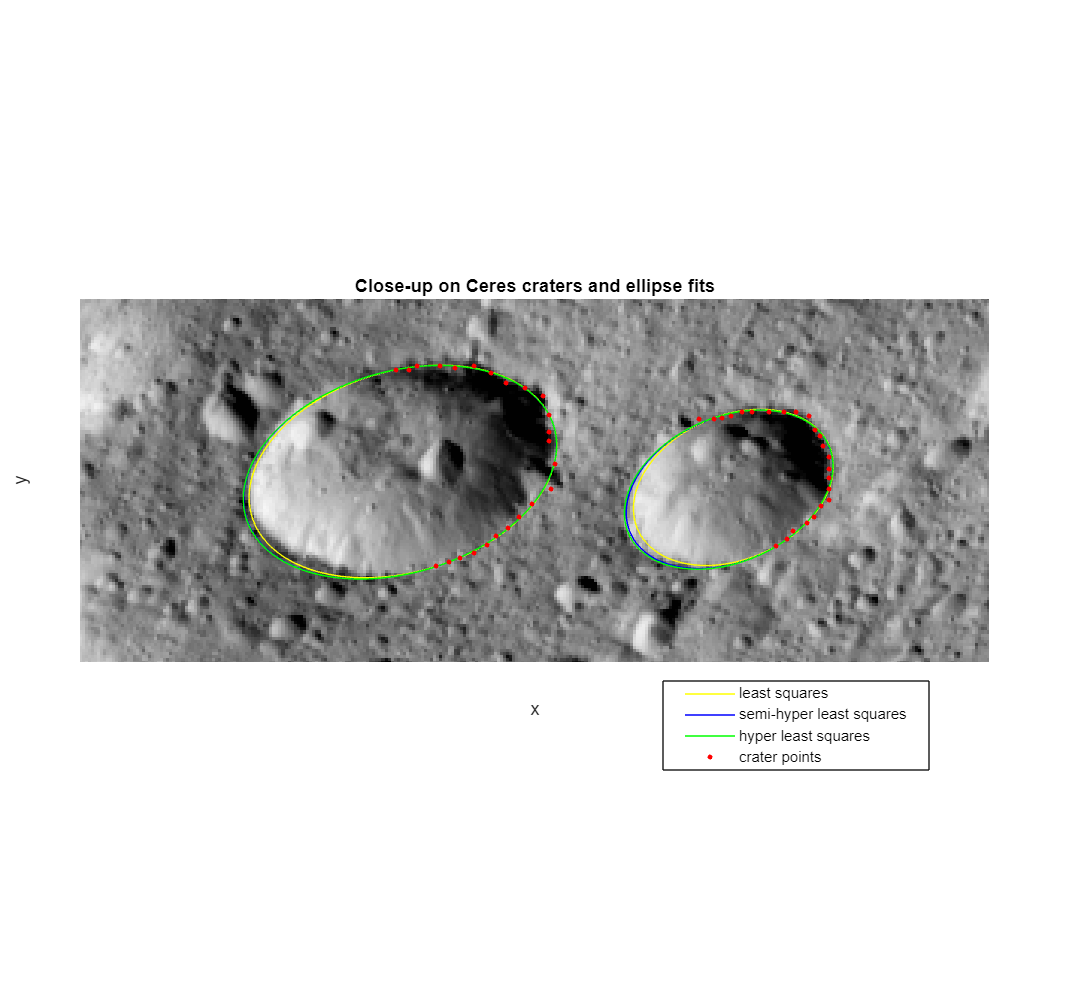

figobj = figure(2); 
imshow(imgPath); hold on; title('Close-up on Ceres craters and ellipse fits');
xlabel('x'); ylabel('y'); fitColors = {'y','b','g'};
for i = 1:ncraters
    XYorig = craterPts{i};
    for j = 1:nfitMthds
        [xfit, yfit] = getEllipse(conicFits{i,j});
        plot(xfit,yfit, 'color', fitColors{j}); 
    end
    plot(xcraterPtsAll{i},ycraterPtsAll{i},'.','MarkerSize', 9,'color','r');
end
xlim([300,600]); ylim([780,900]);
lgObj = legend({'least squares', 'semi-hyper least squares', ...
    'hyper least squares', 'crater points'},'Position', [0.62 0.23 0.25 0.09]);

### References

[1] K. Kanatani and P. Rangarajan, “Hyper least squares fitting of circles and ellipses,” Computational Statistics & Data Analysis, vol. 55, no. 6, pp. 2197–2208, 2011.

%% helper function for computing ellipse locus
function [xf, yf] = getEllipse(conicFit)

    explicitVals = conicFit.explicit;

    % specify theta values to plot
    thetaEps = 0.01; nPts = ceil((2*pi)/thetaEps);
    thetaVals = linspace(0,2*pi,nPts);

    % extract explicit_vals
    xc = explicitVals(1);
    yc = explicitVals(2);
    a = explicitVals(3);
    b = explicitVals(4);
    psi = explicitVals(5);

    % create unit circle
    x = cos(thetaVals);
    y = sin(thetaVals);
    
    % strech into ellipse shape
    x2 = a*x; y2 = b*y;
    
    % translate and rotate
    finalPts = [cos(psi), -1*sin(psi); sin(psi), cos(psi)] * [x2; y2];
    xf = finalPts(1,:) + xc;
    yf = finalPts(2,:) + yc;
end